Зададим параметры сигнала

clear all;
fs=8000;
mas=[15 6 19 21 25 32 7 30];%коды фонем в тестовом сигнале
% mas=12;
fft_size=512;
numcf=15;%количество MFCC коэффициентов
t=0:1/fs:599*1/fs;
f=[2093 293 659 1396 196];% массив частот (5 частот)

freq=[0 100 200 300 500 1000 1500 2000 3000 4000];
Am=[0.005 1 0.5 0.7 0.4 0.3 0.2 0.2 0.2 0.1];
mbFilt = designfilt('arbmagfir','FilterOrder',150, ...
         'Frequencies',freq,'Amplitudes',Am, ...
         'SampleRate',8000);
% fvtool(mbFilt); %смотрим АЧХ фильтра
fir_coefs=mbFilt.Coefficients;

Обучим GMM модель

gm=gmm_learning(f,fs,t,fft_size,numcf,fir_coefs);

Создадим сигнал через нелинейный элемент с кодом в mas

SP=GSS_generation(t,f,mas);
input=gen_frm(SP);
out_nl=nolinear_elmnt(input);
input = fftfilt(fir_coefs, out_nl);

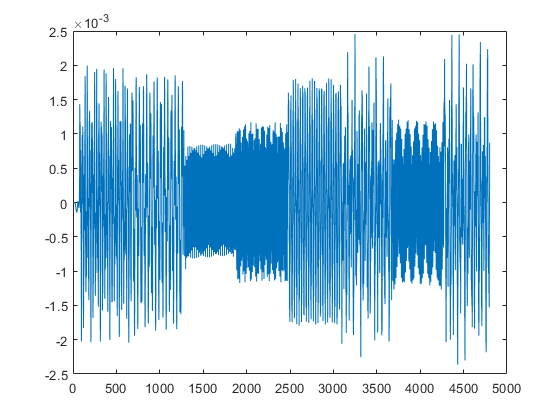


plot(input);

Разделим сигнал на фреймы

winlen      = 25.6;             % window length in ms
winshft     = 25.6;%2.5            % dense window shift in ms
winlen=round(winlen*10^(-3)*fs);
winshft=winshft*10^(-3)*fs;
FrameNo=ceil((length(input)-winlen)/winshft);
frmwin = sig2frm(input, winlen, winshft, FrameNo);

Окно хэминга

[winlen, framenum]=size(frmwin); 
% Hamming window each frame
frmwin = frmwin .* (hamming(winlen) * ones(1, framenum));


Пропустим сигнал через нелинейный элемент и фильтр тракта

% out_nl=nolinear_elmnt(frmwin);
% signal_out = fftfilt(fir_coefs, out_nl);
signal_out=frmwin;

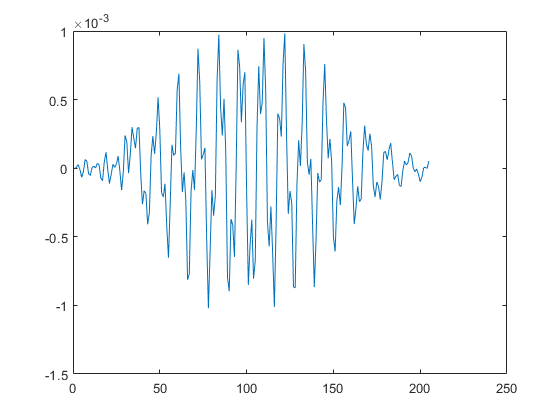


% for i=1:size(signal_out,2)
%     iw=find_excess(signal_out(:,25),fs);
% end
% 
plot(signal_out(:,10));

% fft_sig=fft(out_nl,fft_size);
% Spec = abs(fft_sig(1: fft_size / 2,:));
% Spec=Spec./max(Spec);
% ppl=piople_tract(Spec);
% sig=Spec.*ppl';
% % Spec=genStdSig(t,f,fft_size,mas);

Пронормируем спектр и визуализируем его

% % Spec_db=mag2db(Spec);
% % Freq=linspace(0,fs/2,size(Spec,1));
% % tiledlayout(size(Spec_db,2),1);
% % for i=1:size(Spec_db,2)
% %     nexttile;
% %     plot(Freq,Spec_db(:,i),'k','LineWidth',2);
% %     grid on; grid minor;
% %     xlabel('Частота, Гц');
% %     ylabel('Амплитуда, Дб');
% %     title(['Амплитудный спектр фонемы ' num2str(mas(i)-1)]);
% % end

Найдём MFCC коэффициенты 

cf=mfcc_my(signal_out,fs,fft_size,numcf,0);

Кластеризуем коэффициенты

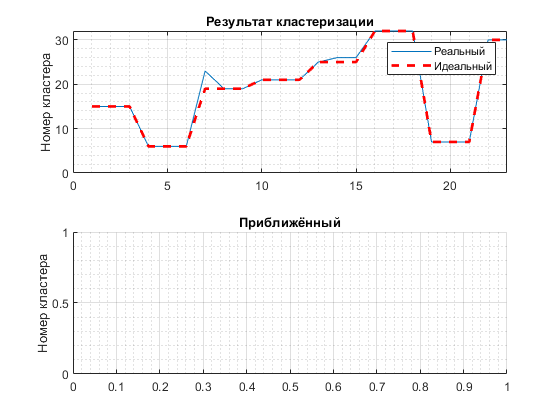

[idx,~,~] = cluster(gm,cf);
id_ver=ver_idx(idx,10);
N=FrameNo/length(mas);
ideal=id_ideal(mas,N);

% er=mas(:)-idx(:);
tiledlayout(2,1);
nexttile;
plot(idx); hold on;
plot(ideal,'r--','LineWidth',2); hold off;
legend('Реальный','Идеальный');
xlim([0 size(idx,1)]);
title('Результат кластеризации');
grid on; grid minor;
ylabel('Номер кластера');
nexttile;
plot(id_ver,'k');
title('Приближённый');
ylabel('Номер кластера');
grid on; grid minor;

probality=length(id_ver)/length(idx);

probality = 0

Использование вейвлет-анализа

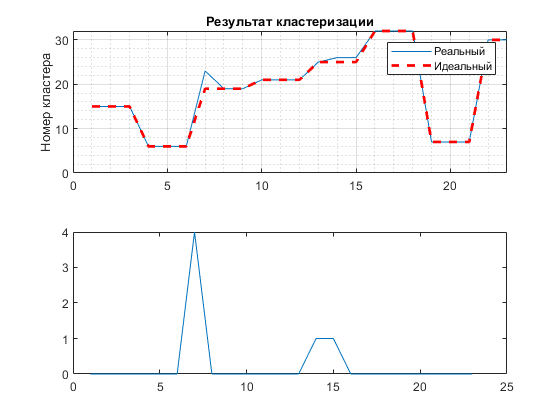

plot(idx-ideal);

probl=idx-ideal;
probl(probl==0)=[];
prblty=(length(idx)-length(probl))/length(idx)

prblty = 0.8696